w= [1000, 1000;
    1130, 1295;
    1190, 1644;
    1253, 1965;
    1802, 2223;
    2200, 2448;
    2079, 2044;
    2112, 2681]

w =         1000        1000
        1130        1295
        1190        1644
        1253        1965
        1802        2223
        2200        2448
        2079        2044
        2112        2681


w=[1000, 1200, 1270, 1272, 1320, 1450, 1700, 1900 2100 2100 2100, 2100 2100;
   1000, 1250, 1500, 1780, 2000, 2150, 2300, 2400 2457 2200 1964  2600 2700]';


[Li, Lj]= runLenghtEncoding(flt',0.2);
Lj=Li;
n= size(Li);
Lj(Li==0)=n(1);
d=0.2*pi/180;
xData= theta2*180/pi;
yData=  (theta1(1)+d*(Lj(:,[1,2])))*180/pi;
hold on
title('RunLength Encoded Plot')
xlabel('theta2 [°]')
ylabel('theta1 [°]')
plot(xData, yData);
hold on

sc= 1024*2/pi;
nn= size(w,1);
wMin = [1000 1000]

wMin =         1000        1000


wMax = [2200 2681]

wMax =         2200        2681


thetaMin=(wMin-1000)/sc

thetaMin =      0     0


thetaMax=(wMax-1000)/sc

thetaMax =     1.8408    2.5786


theta=([w; -1000*ones(32-length(w)-1,2)]-1000)/sc

theta =          0         0
    0.3068    0.3835
    0.4142    0.7670
    0.4172    1.1965
    0.4909    1.5340
    0.6903    1.7641
    1.0738    1.9942
    1.3806    2.1476
    1.6874    2.2350
    1.6874    1.8408


theta=([(w-1000)/sc; zeros(32-length(w),2)])

theta =          0         0
    0.3068    0.3835
    0.4142    0.7670
    0.4172    1.1965
    0.4909    1.5340
    0.6903    1.7641
    1.0738    1.9942
    1.3806    2.1476
    1.6874    2.2350
    1.6874    1.8408


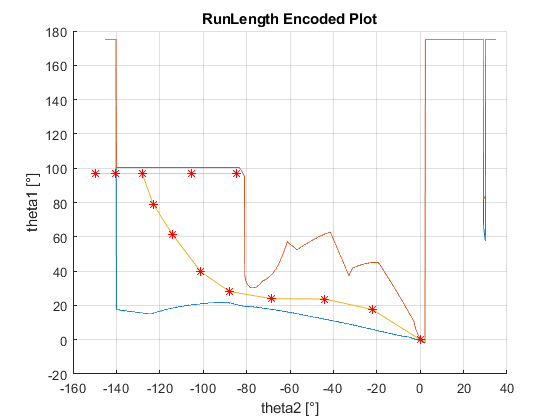

thetaDeg=theta*180/pi;
plot(-thetaDeg(1:nn,2),thetaDeg(1:nn,1))
hold on
plot(-thetaDeg(1:nn,2),thetaDeg(1:nn,1),'r*')
grid on
hold off

fileID = fopen('mainTargets.h','w');
fprintf(fileID,'/*   Data set for Path plannuing or Darc 1000\n   Author: Klaus-Dieter Rupp */\n');
fprintf(fileID,'#ifndef mainTaragets_h\n#define mainTaragets_h\n');
fprintf(fileID,'#define MAX_TARGETS %d\n', 32);
fprintf(fileID,'float minTheta[2] ={%f, %f};\n', thetaMin(1), thetaMin(2));
fprintf(fileID,'float maxTheta[2] ={%f, %f};\n', thetaMax(1), thetaMax(2));
fprintf(fileID,'float targets[][4] ={\n');
fprintf(fileID,'{%f, %f, %f, %f},\n',0,0, 0.1, 1); 
for k=1:length(theta)
    fprintf(fileID,'{%f, %f, %f, %f},\n',theta(k,1),theta(k,2), 0.5, 1); 
end
    fprintf(fileID,'{%f, %f, %f, %f}\n',0,0, 0.5, 1); 

fprintf(fileID,'};\n#endif\n');
fclose (fileID);